# Amortiguación coche

## Definición y Análisis

#### Procedimiento

En este livescript definiremos el modelo, es decir, definiremos sus ecuaciones y constantes. Para su posterior análisis.

#### Ecuaciones del modelo


$$\begin{array}{l}
F_k =K_c \left(x-y\right)\\
F_c =C_c \left(x^{\prime } -y^{\prime } \right)\\
F_r =K_r \left(y-r\right)
\end{array}$$


Ley de Newton


$$\begin{array}{l}
F=m\;a\\
m_c \;{x^{\prime } }^{\prime } =-F_k -F_c \\
m_r {y^{\prime } }^{\prime } =F_k +F_c -F_r 
\end{array}$$


Sustituyendo


$$\begin{array}{l}
{x^{\prime } }^{\prime } =-\frac{C_c }{m_c }x^{\prime } +\frac{C_c }{m_c }y^{\prime } -\frac{K_c }{m_c }x+\frac{K_c }{m_c }y=\\
\frac{1}{m_c }\left(C_c \left({-x}^{\prime } +y^{\prime } \right)+K_c \left(-x+y\right)\right)\\
{y^{\prime } }^{\prime } =\frac{C_c }{m_r }x^{\prime } -\frac{C_c }{m_r }y^{\prime } +\frac{K_c }{m_r }x-\frac{K_c }{m_r }y-\frac{K_r }{m_r }y+\frac{K_r }{m_r }r=\\
\frac{1}{m_r }\left(C_c \left(x^{\prime } -y^{\prime } \right)+K_c \left(x-y\right)+K_r \left(-y+r\right)\right)
\end{array}$$


#### Constantes del modelo


$$\begin{array}{l}
m_c \\
m_r \\
t_{inicial} =0\\
t_{final} =20
\end{array}$$


Limpieza del entorno de trabajo

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

Habiendo definido el modelo se configura en el archivo sim_utils.m (véase sim_utils.m) y se toman de este las configuraciones:

[cfg, model_names, CI] = sim_utils();

Esto es: configuraciones de solver, plot, scatter, xlabel, ylable, title, junto con los nombres y las condiciones iniciales de los modelos.

#### Simulación

Al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo para una configuración de solver almacenada en cfg.solver (véase sim_utils.m)

signals = sim_config(model_names{2}, cfg.solver{1});
num_signals = numElements(signals);

Se dibuja cada señal

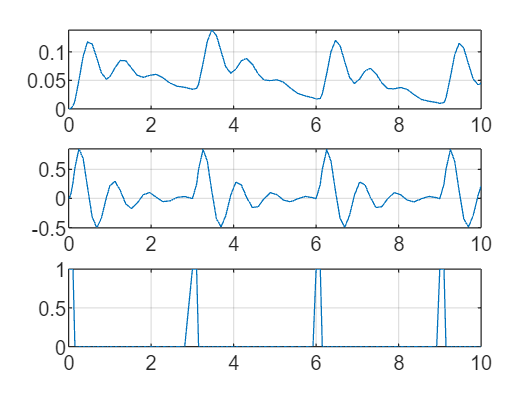

for i=1:num_signals
    t = signals{i}.Values.Time;
    y = signals{i}.Values.Data;
    subplot(3, 1, i)
    plot(t, y, cfg.plot{1}{:})

    xlim([t(1), t(end)]);
    ylim([min(y), max(y)])
    % xlabel(cfg.xlabel{1}{:})
    % ylabel(cfg.ylabel{1}{:})
    % title(cfg.title{1}{:})
    % legend('show','location','best');
    grid on
end

## Funciones disponibles para todas las secciones:

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

#### Decorador de la función sim de MATLAB

Esta función ejecuta la función sim, tras establecer los parámetros del solver.

function signals = sim_config(model_name, solver_config)
% Simulate a model with a custom solver
% Returns Dataset with signal of each Out1 block
% Note: In a signal, for multiple conditions, multiple values
% INPUTS
% ------------------------------------------
% model_name = string
% solver_config = cell array
%
% OUTPUTS
% ------------------------------------------
% signals = Simulink.SimulationData.Dataset

load_system(model_name)
% open_system(model_name) will also open it

% Set solver parameters
set_param(model_name, solver_config{:})

% Simulation Output
sim_data = sim(model_name);
signals = sim_data.yout; % Dataset container of signals
end

#### Consideraciones adicionales Simulink

Se utiliza el bloque Out1 para cada señal debido a que:

- No usaremos bloques Bus para no formatear los nombres, ejemplo: MATLAB transforma '+' a '_'

- No usaremos bloques To Workspace para iterar más fácil, iteramos el contenido de .yout

- Es posible el manejo de múltiples condiciones iniciales sin problema

#### Scripts adicionales

Para obtener cada señal se puede usar: 

% signals{index}
% signals.getElement('signal_name')

Los valores de una señal se encuentran en el campo Values

% signals{index}.Values.Data
% signals{index}.Values.Time
% signals{index}.Values.Name

Inicio y fin de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% start_value = signals{1}.Values.Data(1);
% end_value = signals{1}.Values.Data(end);

Máximo y mínimo de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% [signal_max, index_max] = max(signals{1}.Values.Data);
% point_max = [signals{1}.Values.Time(index_max), signal_max];
%
% [signal_min, index_min] = min(signals{1}.Values.Data);
% point_min = [signals{1}.Values.Time(index_min), signal_min];

Media de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% signal_mean = mean(signals{1}.Values.Data)

Autor: Alfredo Robledano Abasolo 3ºB Ingeniería Matemática UFV (2023-2024)